# Data Analytics: Filtering and basic pattern recognition

#### by Rodolfo Muñoz

clear variables; close all; clc;

First we start by letting the user select the file.

[filename,path] = uigetfile('*.xls');
colors = [0.4 0.5 1; 0 0 0];

Then, we load the data into a datastore in case its a big file and select to read only one sheet at a time. Then we preview the table to select the data we need for the analysis. 

tabds = datastore([path filename],'Type',"spreadsheet");

tabds.ReadSize = 'sheet';
preview(tabds)

ans = 8×21 table
    RowID         OrderID           OrderDate      ShipDate           ShipMode          CustomerID        CustomerName           Segment            Country                City                State         PostalCode     Region           ProductID              Category           Sub_Category                                  ProductName                                 Sales     Quantity    Discount    Profit 
    _____    __________________    ___________    ___________    __________________    ____________    __

For this analysis we'll look over the sales values so we'll retrieve only a handful of columns from the table.

tabds.SelectedVariableNames = {'OrderDate','Sales','Quantity','Profit'};
tab = read(tabds);
sales = groupsummary(tab,{'OrderDate'},'sum');
stats.mean_Sales = mean(sales.sum_Sales); 
stats.mean_Quantity = mean(sales.sum_Quantity); 

## Plot sales data vs time

Now we plot the results to look at the data and guide the analysis:

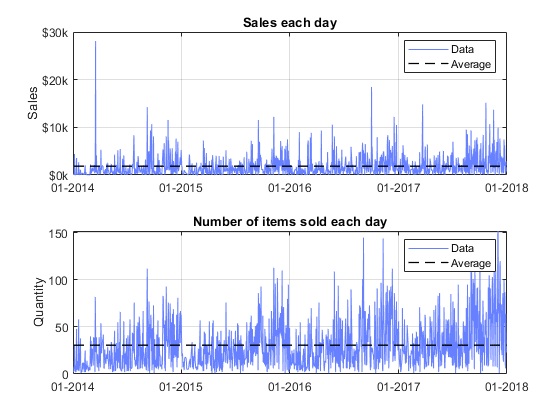

figure('name','sales');
subplot(2,1,1)
plotSales(sales.OrderDate,sales.sum_Sales,'$','lines',{'mean'});

subplot(2,1,2)
plotSales(sales.OrderDate,sales.sum_Quantity,'qty','lines',{'mean'});

## Analyze its frequency components

By looking at the *Quantity sales plot*, there seems to be a yearly pattern on the company. For further analysis, we use the Fourier Transform to check the data in the frequency domain and see the low frequency components to verify this pattern.  

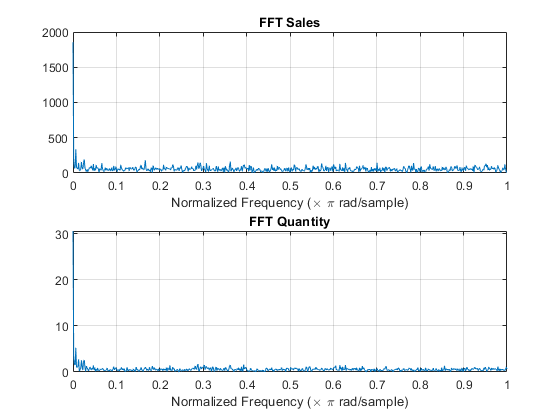

F_s = fft(sales.sum_Sales); F_s = F_s/length(F_s);
F_q = fft(sales.sum_Quantity); F_q = F_q/length(F_q);
w = (0:length(F_s)-1)/(length(F_s)-1)*2;

figure('name','FFT Sales');
subplot(2,1,1)
plot(w,abs(F_s))
xlim([0 1])
xlabel('Normalized Frequency (\times \pi rad/sample)')
title('FFT Sales')
grid on
subplot(2,1,2)
plot(w,abs(F_q))
xlim([0 1])
xlabel('Normalized Frequency (\times \pi rad/sample)')
title('FFT Quantity')
grid on

Both plots, specially the quantity one, seem to have a higher data concentration below $\omega =0\ldotp 05$. Therefore, we'll use a Chevyshev-II Low Pass Filter to look at the filtered data

## Filter sales data

For this, we need to define the atenuation parameters of our filter and the cut frequencies.

Wp = 0.1;  % Passband frequency
Ws = Wp + 0.05;                    % Stopband frequency
Rp = 3;                            % Passband ripple (dB)
Rs = 60;                           % Stopband atenuation (dB)

[n,Ws] = cheb2ord(Wp,Ws,Rp,Rs);
[b,a] = cheby2(n,Rs,Ws);

And apply the resulting filter on the **sales.sum_Quantity** data:

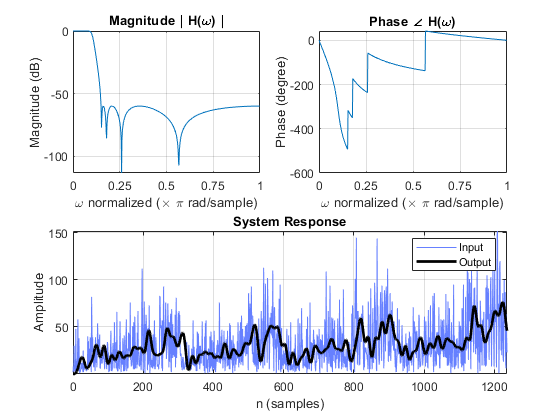

figure('name','Filter effect on data');
filterresponse(b,a,sales.sum_Quantity,'colors',colors,'magplot','indb','linewidth',2);

While the filtered data shows the pattern we intuited before, it has a *phase delay* that distorts the signal. This distortion makes it so the peaks of the filtered data do not align with the peaks of the original. For that reason, we use Matlab's built-in function *filtfilt* to apply the filter and remove the effect of the phase delay:

sales_smooth.qty = filtfilt(b,a,sales.sum_Quantity);
sales_smooth.sales = filtfilt(b,a,sales.sum_Sales);

Additionaly, we're going to fill the gaps in sales data with a linear interpolation. We do this because there were no sales in some days, and given that we're checking for macro/global patterns we want smooth continuous lines.

sales_smooth.dates = min(sales.OrderDate):max(sales.OrderDate);
sales_smooth.years = unique(year(sales_smooth.dates));
sales_smooth.sales = interp1(sales.OrderDate,sales_smooth.sales,sales_smooth.dates);
sales_smooth.qty = interp1(sales.OrderDate,sales_smooth.qty,sales_smooth.dates);

And we see the results.

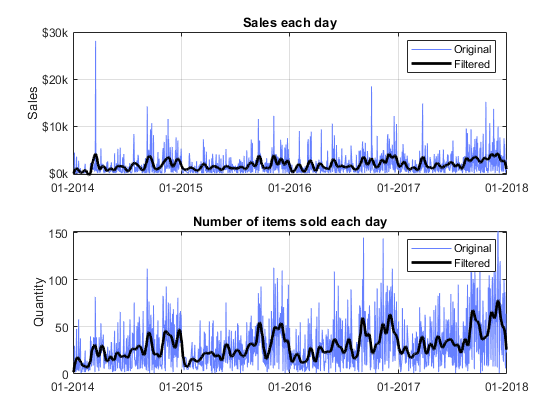

figure("Name","Filtered data")
subplot(2,1,1)
plotSales(sales.OrderDate,sales.sum_Sales,'$')
hold on;
plot(sales_smooth.dates,sales_smooth.sales/1e3,'color',colors(2,:),"LineWidth",2)
hold off;
legend('Original','Filtered')

subplot(2,1,2)
plotSales(sales.OrderDate,sales.sum_Quantity,'qty')
hold on;
plot(sales_smooth.dates,sales_smooth.qty,'color',colors(2,:),"LineWidth",2)
hold off;
legend('Original','Filtered')

% fig2pdf('FilteredSales')

## Daily sales comparison

Now that we've confirmed the pattern, we plot the sales data by year so we can see them side-by-side. 

In order to match all plotlines in the same graph, we'll add a normalized datetime array **sales_smooth.dateYearless** to the table. 

This array will consist of the same *dates* as **sales_smooth.dates** the original, but with their year equalized to the first leap year present in the data.

u = sales_smooth.dates;                                         % Preallocation for speed
bisiesto = min(u).Year;                                         % Default case
if(~isempty(find((u.Day == 29).*(u.Month == 2),1)))
    bisiesto = u(find((u.Day == 29).*(u.Month == 2), 1)).Year;  % Selecting the leap year
end
sales_smooth.dateYearless = sales_smooth.dates;
sales_smooth.dateYearless.Year = bisiesto;
N = length(sales_smooth.years);

The actual plot:

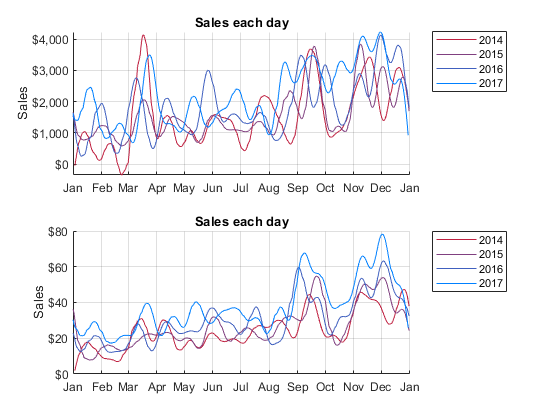

figure('Name','Daily sales comparisson');
subplot(2,1,1); hold on;
for i=1:N
    idx = (year(sales_smooth.dates) == sales_smooth.years(i));
    plotSales(sales_smooth.dateYearless(idx),sales_smooth.sales(idx),'color',[1-i/N 0.5*i/N i/N]);
end
hold off;
xticks(datetime(bisiesto,1:13,1))
datetick('x','mmm','keepticks')
legend(num2str(sales_smooth.years'),'Location',"northeastoutside")

subplot(2,1,2); hold on;
for i=1:N
    idx = (year(sales_smooth.dates) == sales_smooth.years(i));
    plotSales(sales_smooth.dateYearless(idx),sales_smooth.qty(idx),'color',[1-i/N 0.5*i/N i/N]);
end
hold off;
xticks(datetime(bisiesto,1:13,1))
datetick('x','mmm','keepticks')
legend(num2str(sales_smooth.years'),'Location',"northeastoutside")